## **Session 3**

# **Inferential statistics, Power, multiple Comparisons**

## **Inferential Statistics, Power, Multiple Comparisons and Theoretical Aspects**

**The Logic of Hypothesis Testing**

- **Core Idea**: Using sample data to make inferences about a larger population.

**Null Hypothesis (**H0**)**

- **Definition**: A statement of no effect, no difference, or no relationship. It's the default assumption we try to disprove.

- **Example**: "There is no difference in ERP amplitude between Condition A and Condition B."

**Alternative Hypothesis (**H1** or **HA**)**:

- **Definition**: A statement that contradicts the null hypothesis, suggesting an effect, difference, or relationship exists. This is what the researcher is often trying to find evidence for.

- **Example**: "There is a difference in ERP amplitude between Condition A and Condition B."

**P-value**:

- **Definition**: In the context of the EEG data, the **null hypothesis** is that there is **no difference** in ERP amplitude between the Incongruent and Congruent conditions. The **p-value** tells you how likely it is to observe the difference you found, assuming no real difference exists. A small p-value lets you conclude that there truly is a difference.

- **Interpretation**: A small p-value suggests that the observed data is unlikely under the null hypothesis, leading us to question the null.

- **Common Misconceptions**: Not the probability that H0 is true, or the probability of replicating the result.

**Significance Level (**α**)**:

- **Definition**: A pre-determined threshold (e.g., 0.05 or 0.01) for the p-value.

- **Decision Rule**: If p<α, we reject H0. If p≥α, we fail to reject H0.

- **Relationship to Type I Error**: α is the maximum acceptable probability of making a Type I error

**Confidence Intervals (CI)**:

- **Definition**: A range of values that, with a specified probability (the confidence level, e.g., 95%), is likely to contain the true population parameter (e.g., mean difference).

- **Interpretation**: If a 95% CI for a difference includes zero, then the difference is not statistically significant at α=0.05. If it does not include zero, the difference is significant.

- **Advantages**: Provides more information than just a p-value (magnitude and precision of effect).

 **Errors in Hypothesis Testing**

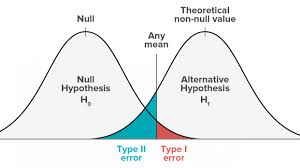

   **Type I Error (**α**) - False Positive**:

- **Definition**: Rejecting the null hypothesis when it is actually true.

- **Analogy**: Crying "wolf!" when there is no wolf.

- **Consequences**: Publishing false findings, wasted research efforts.

- **Control**: Set a strict α level (e.g., 0.05, 0.01).

**Type II Error (**β**) - False Negative**:

- **Definition**: Failing to reject the null hypothesis when it is actually false.

- **Analogy**: Failing to detect a wolf when there is one.

- **Consequences**: Missing a true effect, failing to publish important findings

**Statistical Power (**1−β**)**:

- **Definition**: The probability of correctly rejecting a false null hypothesis. It's the ability of a test to detect an effect if one truly exists.

- **Goal**: Maximize power while controlling Type I error.

## **Statistical Power**

**Statistical power** is the probability of a statistical test correctly detecting an effect when one truly exists. In simpler terms, it's your ability to find a real difference if there is one. In other words, it's the likelihood of avoiding a **Type II error** (a "false negative").

It is typically represented as 1−β, where β is the probability of a Type II error. Researchers commonly aim for a power of **80% (or 0.8)**, meaning there's an 80% chance of detecting a true effect if it's there.

**Why is it Important in Neuroscience?**

- **Avoiding False Negatives**: Neuroscience phenomena can be subtle. Low power means a study might miss genuine brain effects, leading to wasted resources and incomplete understanding.

- **Reliability and Replicability**: Studies with adequate power are more reliable and their findings are more likely to be replicated by other researchers.

- **Ethical Considerations**: Especially in clinical trials, it's unethical to expose participants to interventions if the study is too underpowered to detect a benefit or harm.

- **Resource Allocation**: Power analysis helps determine the necessary sample size *before* data collection, optimizing time, money, and participant recruitment.

**Relationship with Type I and Type II Errors**

To understand power, it's important to grasp the two types of errors in hypothesis testing:

- **Type I Error (****α****)**: The probability of **incorrectly rejecting a true null hypothesis** (a "false positive"). This means concluding there's an effect when there isn't one. The α level (significance level), commonly set at 0.05, defines this probability.

- **Type II Error (****β****)**: The probability of **failing to reject a false null hypothesis** (a "false negative"). This means concluding there's no effect when one truly exists. Statistical power is directly related to Type II error: Power=1−β

There's often a **trade-off** between Type I and Type II errors. For example, decreasing α (making it harder to find a significant result) reduces the risk of a Type I error but increases the risk of a Type II error, thus decreasing power.

## Factors Influencing Statistical Power

Statistical power is influenced by three main factors, all of which researchers can (to varying degrees) control or estimate:

**Effect Size (Magnitude of the Effect)**:

- This is the true difference or relationship you're trying to detect. A **larger effect size** (e.g., a big difference in ERP amplitude between two conditions) is easier to detect, thus **increasing power**.

- In the context of EEG, improving **Signal-to-Noise Ratio (SNR)** through preprocessing (like filtering) effectively increases the observed effect size relative to the noise, thereby boosting power.

**Sample Size (N)**:

- A **larger sample size** (more trials, more participants) generally leads to **higher power**. This is because larger samples provide more precise estimates of population parameters, reducing the standard error of the mean difference.

- As N increases, the sampling distribution of the mean becomes narrower, making it easier to distinguish between the null and alternative hypotheses.

**Significance Level (α****)**:

- This is the threshold for declaring statistical significance (e.g., p<0.05). A **higher ****α**** value** (e.g., 0.10 instead of 0.05) makes it easier to reject the null hypothesis, thus **increasing power**.

- However, increasing α also increases the risk of a Type I error, which is generally undesirable in scientific research.

**How Preprocessing Impacts Statistical Power with this Data:**

- **Low Power (Unfiltered)**: With the raw data, the noise in each trial is high. When you average across trials, the noise is reduced, but it's not completely gone. This remaining noise still contributes to the overall variability, making the standard error larger. A large denominator in the t-test formula results in a smaller `t`-value, making it harder to reach statistical significance. This means you have a **lower chance of finding a significant difference** between conditions, even if one truly exists.

- **High Power (Filtered)**: When you filter the data, you reduce the noise and therefore the variability. The standard error becomes smaller. A smaller denominator in the t-test formula results in a larger `t`-value, making it easier to reach statistical significance. This means you have a **higher chance of finding a significant difference**, thus increasing the study's statistical power.

## **Kolmogorov-Smirnov Test (KS Test)**

The Kolmogorov-Smirnov (KS) test is a non-parametric test used in statistics to compare two distributions. It measures the distance between the empirical distribution functions of two samples or between a sample distribution and a reference distribution. Here’s a detailed explanation:

### Purpose

The KS test is used to determine if:

- A sample comes from a population with a specific distribution (one-sample KS test).

- Two samples come from the same distribution (two-sample KS test).

### **Hypotheses**

#### One-sample KS test:

Null hypothesis (Ho): The sample comes from the reference distribution

Alternative hypothesis (Ha): The sample does not come from the reference distribution

#### **Two-sample KS test:**

Null hypothesis (Ho): The two samples come from the same distribution.

Alternative hypothesis (Ha): The two samples come from different distributions.

**P-value**

The p-value for the KS test can be calculated using the distribution of the KS statistic under the null hypothesis. If the p-value is less than the chosen significance level (e.g., 0.05), the null hypothesis is rejected.

For large samples, the null hypothesis is rejected at level:

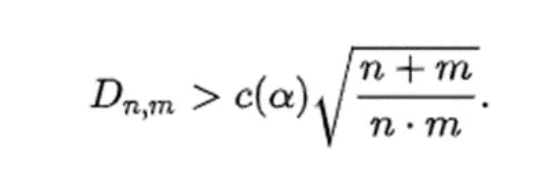

Where 𝑛 Nand 𝑚 are the sizes of first and second sample respectively. The value of 𝑐(𝛼) is given in the table below for the most common levels of 𝛼:

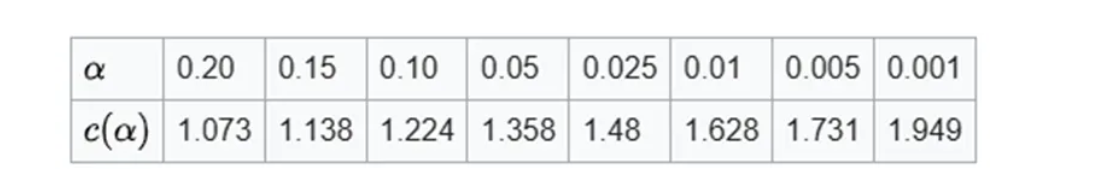

### Uses

**Goodness-of-Fit Test:** To check if a sample follows a specific distribution (e.g., normal, exponential).

**Comparing Two Samples:** To test if two independent samples come from the same distribution.

**Model Validation:** To validate assumptions about data distribution in various statistical models.

**Hypothesis Testing:** To perform non-parametric hypothesis tests without assuming specific distributions.

### Advantages

**Non-parametric:** No assumption about the underlying distribution.

Applicable to continuous and discrete data.

Sensitive to differences in both location and shape of the empirical cumulative distribution functions.

### Limitations

Less powerful compared to other tests if specific parametric assumptions can be made.

For large samples, small differences can lead to rejection of the null hypothesis.

## **Parametric Statistical Tests**

**Assumptions of Parametric Tests**:

- **Normality**: Data (or residuals) are normally distributed.

- **Homogeneity of Variance**: Variances of the populations from which samples are drawn are equal.

- **Independence**: Observations are independent of each other (unless explicitly designed as paired/repeated measures).

- **Interval/Ratio Data**: Dependent variable is measured on an interval or ratio scale.

**t-tests**:

- **Purpose**: Comparing means of one or two groups.

- **One-Sample t-test**: Compares the mean of a single sample to a known or hypothesized population mean (e.g., "Is the average ERP amplitude significantly different from zero?").

- **Independent Samples t-test**: Compares the means of two *independent* groups (e.g., "Is the ERP amplitude different between patients and controls?").

- **Paired Samples t-test**: Compares the means of two *related* samples (e.g., "Is the ERP amplitude different between Condition A and Condition B in the *same* subjects?").

**ANOVA (Analysis of Variance)**:

- **Purpose**: Comparing means of *three or more* groups or conditions. Extends the t-test.

- **Concept of F-statistic**: Ratio of variance *between* groups to variance *within* groups. A large F-value suggests group means are more different than within-group variability.

- **One-Way ANOVA**: For one categorical independent variable with 3+ levels (e.g., comparing ERP amplitude across three stimulus types).

- **Multi-factor ANOVA (e.g., Two-Way ANOVA)**: For designs with two or more categorical independent variables (e.g., comparing ERP amplitude by stimulus type AND gender).

**Post-hoc Tests**:

- **Why Needed**: A significant ANOVA only tells you that *at least one*  group mean is different, not *which* specific groups differ.

- **Purpose**: Perform pairwise comparisons between group means after a significant ANOVA.

- **Examples**: Tukey's Honestly Significant Difference (HSD), Bonferroni correction (adjusts p-values for multiple comparisons).

**Non-parametric Test**

- **When to Use**:

- When parametric assumptions (especially normality) are severely violated

- When data is ordinal or ranked.

- When sample sizes are very small

**Brief Overview**:

- **Wilcoxon Rank-Sum Test (Mann-Whitney U-test)**: Non-parametric alternative to the independent samples t-test. Compares medians or distributions, not means.

- **Wilcoxon Signed-Rank Test**: Non-parametric alternative to the paired samples t-test. Compares medians of paired differences.

- **Trade-offs**:

- **Advantages**: Fewer assumptions, robust to outliers.

- **Disadvantages**: Generally less statistical power than parametric tests if assumptions are met.

clear;
clc;
warning('off', 'all');
% restoredefaultpath
% addpath('C:\matlab_path\eeglab2025.0.0');
% eeglab('nogui');

% load datasets:
load('cz_PSD_trials_class1.mat');
class_1 = cz_PSD_trials_class1;
mean_class_1 = mean(class_1(:,1:6),2);

load('cz_PSD_trials_class2.mat');
class_2 = cz_PSD_trials_class2;
mean_class_2 = mean(class_2(:,1:6),2);


[h, p] = lillietest(mean_class_1);

fprintf('h = %d\n', h);

h = 0


fprintf('p-value = %.4f\n', p);

p-value = 0.1666


[h, p] = lillietest(mean_class_2);

fprintf('h = %d\n', h);

h = 0


fprintf('p-value = %.4f\n', p);

p-value = 0.5000


[h, p, ksstat] = kstest2(mean_class_1, mean_class_2);

fprintf('h = %d\n', h);

h = 1


fprintf('p-value = %.4f\n', p);

p-value = 0.0131


fprintf('KS statistic = %.4f\n', ksstat);

KS statistic = 0.2200


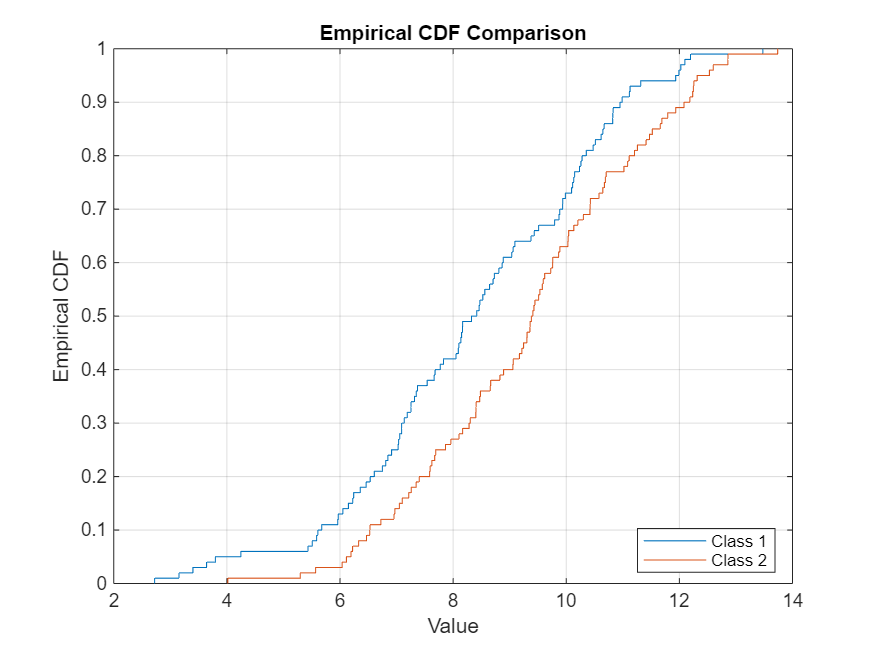

figure;
cdfplot(mean_class_1); hold on;
cdfplot(mean_class_2);

legend('Class 1','Class 2','Location','best');
xlabel('Value');
ylabel('Empirical CDF');
title('Empirical CDF Comparison');
grid on;

% --- Part 2: The Logic of Hypothesis Testing ---

% This script loads the data and performs a paired t-test
% to test the hypothesis of no difference between conditions.

fprintf('--- Part 2: Paired t-test for Hypothesis Testing ---\n');

--- Part 2: Paired t-test for Hypothesis Testing ---



% Define the null and alternative hypotheses.
fprintf('  H0: There is no difference in Power Spectrums between the conditions.\n');

  H0: There is no difference in Power Spectrums between the conditions.


fprintf('  H1: There is a difference.\n');

  H1: There is a difference.



% Pre-determined significance level
alpha = 0.05; 
fprintf('  Significance level (alpha) = %.2f\n', alpha);

  Significance level (alpha) = 0.05



% Perform a paired t-test on the Power Spectrums.
% The 'ttest' function returns the decision (h), p-value, confidence interval, and stats.
[h, p_value, ci, stats] = ttest2(mean_class_1, mean_class_2, 'Alpha', alpha);

fprintf('\n  Paired t-test results:\n');


  Paired t-test results:


fprintf('    t-statistic = %.2f\n', stats.tstat);

    t-statistic = -3.26


fprintf('    Degrees of freedom (df) = %d\n', stats.df);

    Degrees of freedom (df) = 198


fprintf('    p-value = %.4f\n', p_value);

    p-value = 0.0013


fprintf('    95%% Confidence Interval for the mean difference = [%.2f, %.2f] uV\n', ci(1), ci(2));

    95% Confidence Interval for the mean difference = [-1.55, -0.38] uV



% Decision based on p-value and alpha
if h == 1
    fprintf('\n  Decision: Since p < alpha, we REJECT the null hypothesis.\n');
    fprintf('  Conclusion: There is a statistically significant difference in Power Spectrum.\n');
else
    fprintf('\n  Decision: Since p >= alpha, we FAIL TO REJECT the null hypothesis.\n');
    fprintf('  Conclusion: We do not have enough evidence to say there is a difference.\n');
end


  Decision: Since p < alpha, we REJECT the null hypothesis.


  Conclusion: There is a statistically significant difference in Power Spectrum.



% Check CI for significance
if ci(1) > 0 || ci(2) < 0
    fprintf('  Confidence Interval check: The CI does not contain zero, consistent with a significant result.\n');
else
    fprintf('  Confidence Interval check: The CI contains zero, consistent with a non-significant result.\n');
end

  Confidence Interval check: The CI does not contain zero, consistent with a significant result.



% Save the difference scores for use in other scripts
diff_scores = mean_class_2 - mean_class_1;
save('diff_scores.mat', 'diff_scores');

fprintf('\n--- Part 2 Complete. Now run part3_statistical_power.m ---\n');


--- Part 2 Complete. Now run part3_statistical_power.m ---


% non-parametric test
[p_ranksum, h_ranksum, stats_ranksum] = ranksum(mean_class_1, mean_class_2);

fprintf('\n--- Mann-Whitney U test (ranksum) ---\n');


--- Mann-Whitney U test (ranksum) ---


fprintf('p-value = %g\n', p_ranksum);

p-value = 0.0033015


fprintf('U statistic = %g\n', stats_ranksum.ranksum);

U statistic = 8847


## **Cohen’s d **

**Cohen’s d ** is a standardized measure of **effect size** — it tells you *how large* the difference is between two group means, in units of standard deviation.

It is commonly used in psychology, neuroscience, medicine, and any field comparing groups.

### Interpretation (Cohen's suggested thresholds)

These are rough guidelines — interpretation can depend on the field.

### What Cohen’s d tells you

- **ttest / p-value tells you if groups differ statistically** (significance)

- **Cohen’s d tells you how big the difference is** (practical importance)

It’s possible to have:

- small p-value but tiny d → statistically significant but *not ****meaningful***

- large d but non-significant → meaningful effect but low sample size

So Cohen’s d is extremely important.

% --- Part 3: Statistical Power Analysis ---

% This script demonstrates how to calculate statistical power and the
% required sample size, which are crucial for study design.


fprintf('--- Part 3: Understanding Statistical Power ---\n');

--- Part 3: Understanding Statistical Power ---


fprintf('  Power is the probability of correctly rejecting a false H0.\n');

  Power is the probability of correctly rejecting a false H0.


fprintf('  It depends on sample size, effect size, and alpha.\n');

  It depends on sample size, effect size, and alpha.



% Calculate Cohen's d (a measure of effect size) for the observed data.
mean_diff = mean(diff_scores);
pooled_std = std(diff_scores);
cohens_d = abs(mean_diff) / pooled_std;
fprintf('\n  Observed Effect Size (Cohen''s d) = %.2f\n', cohens_d);


  Observed Effect Size (Cohen's d) = 0.36




% Use MATLAB's power analysis function to show how power changes with sample size.
% We assume the observed effect size is the true effect.
alpha = 0.05;
target_power = 0.8;
fprintf('\n  Goal: What sample size do we need for 80%% power to detect this effect?\n');


  Goal: What sample size do we need for 80% power to detect this effect?



% This requires the Statistics and Machine Learning Toolbox

% Calculate required sample size for 80% power
n_required = sampsizepwr('t', [0 pooled_std], mean_diff, target_power, [], 'Alpha', alpha, 'Tail', 'both');
fprintf('    Required sample size (N) for %.0f%% power: %d\n', target_power*100, ceil(n_required));

    Required sample size (N) for 80% power: 62



% Also demonstrate how power changes with more trials
% Corrected: We now specify [] for the 'power' parameter to solve for it.
power_at_100_trials = sampsizepwr('t', [0 pooled_std], mean_diff, [], 100, 'Alpha', alpha, 'Tail', 'both');
fprintf('    Statistical Power at N=100: %.2f (%.0f%%)\n', power_at_100_trials, power_at_100_trials*100);

    Statistical Power at N=100: 0.95 (95%)




fprintf('\n--- Part 3 Complete. Now run part4_multiple_comparisons.m ---\n');


--- Part 3 Complete. Now run part4_multiple_comparisons.m ---


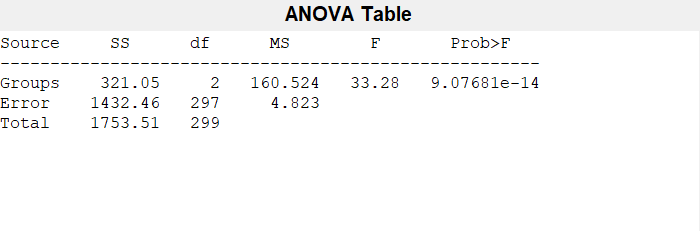

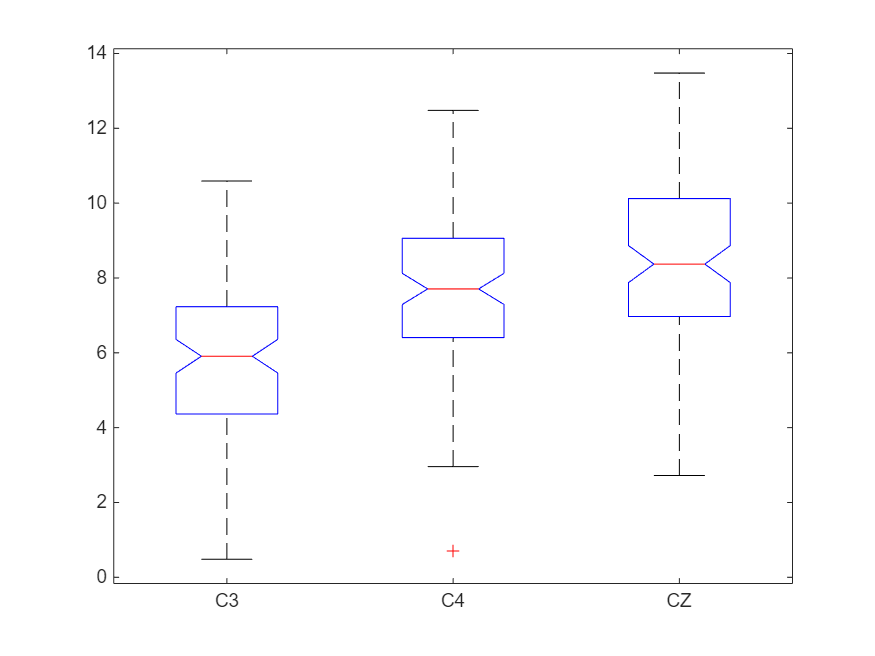

clear;
clc;
load('c3_PSD_trials_class1.mat'); 
c3_class1 = c3_PSD_trials_class1;
c3 = mean(c3_class1(:,1:6),2);
load('c4_PSD_trials_class1.mat'); 
c4_class1 = c4_PSD_trials_class1;
c4 = mean(c4_class1(:,1:6),2);
load('cz_PSD_trials_class1.mat'); 
cz_class1 = cz_PSD_trials_class1;
cz = mean(cz_class1(:,1:6),2);

data = [c3(:); c4(:); cz(:)];       % column vector of all data
group = [repmat({'C3'}, length(c3), 1);
         repmat({'C4'}, length(c4), 1);
         repmat({'CZ'}, length(cz), 1)];  % group labels


[p, tbl, stats] = anova1(data, group);


fprintf('p-value = %g\n', p);

p-value = 9.07681e-14


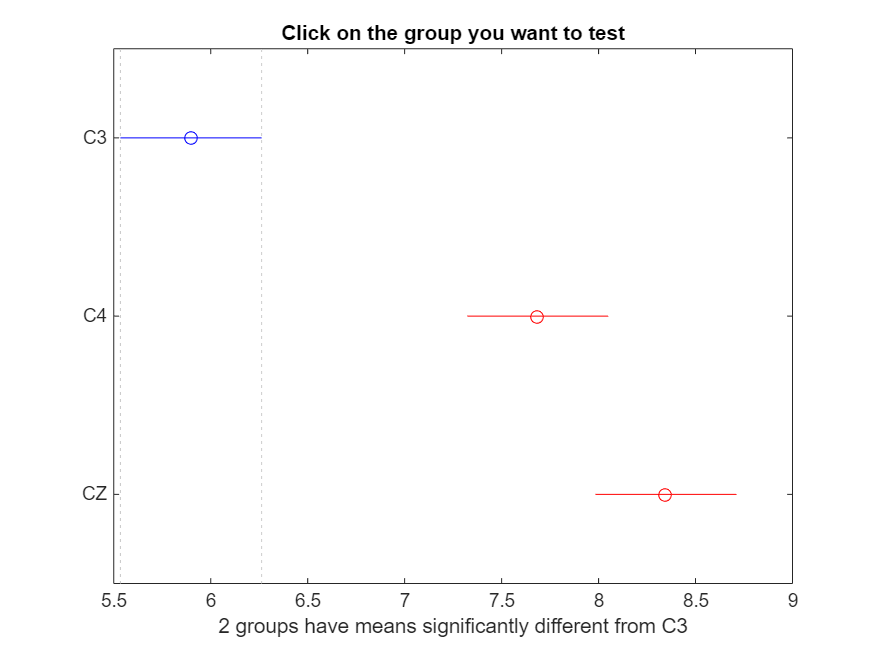

% Tukey’s HSD
[c, m, h, gnames] = multcompare(stats, 'CType', 'tukey-kramer');

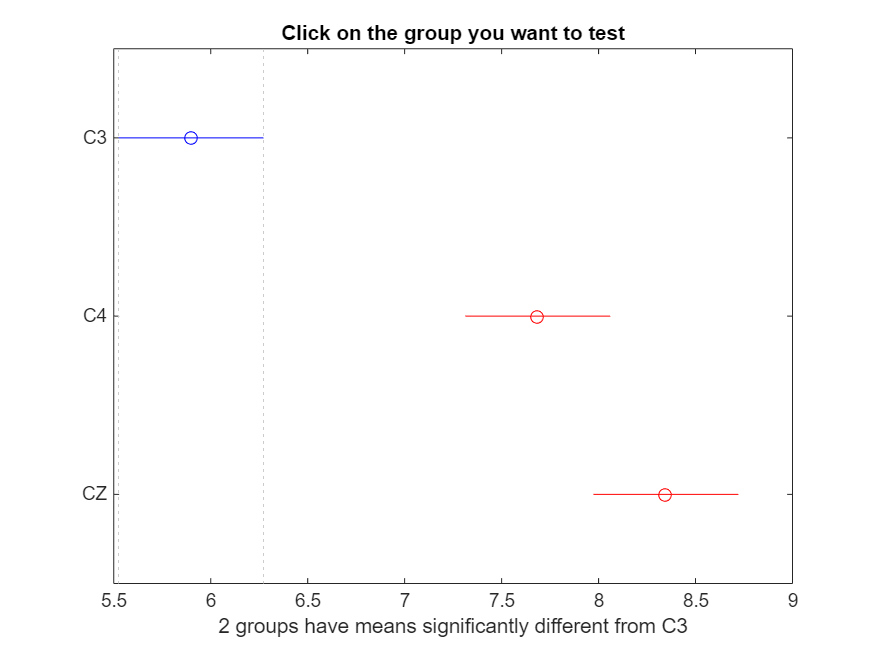

% Bonferroni post-hoc test
[c, m, h, gnames] = multcompare(stats, 'CType', 'bonferroni');

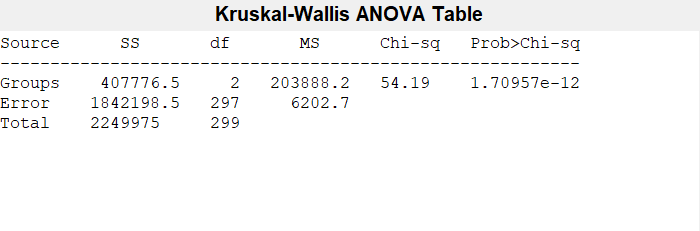

% Non-parametric test: Kruskal-Wallis
[p_kw, tbl_kw, stats_kw] = kruskalwallis(data, group);

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


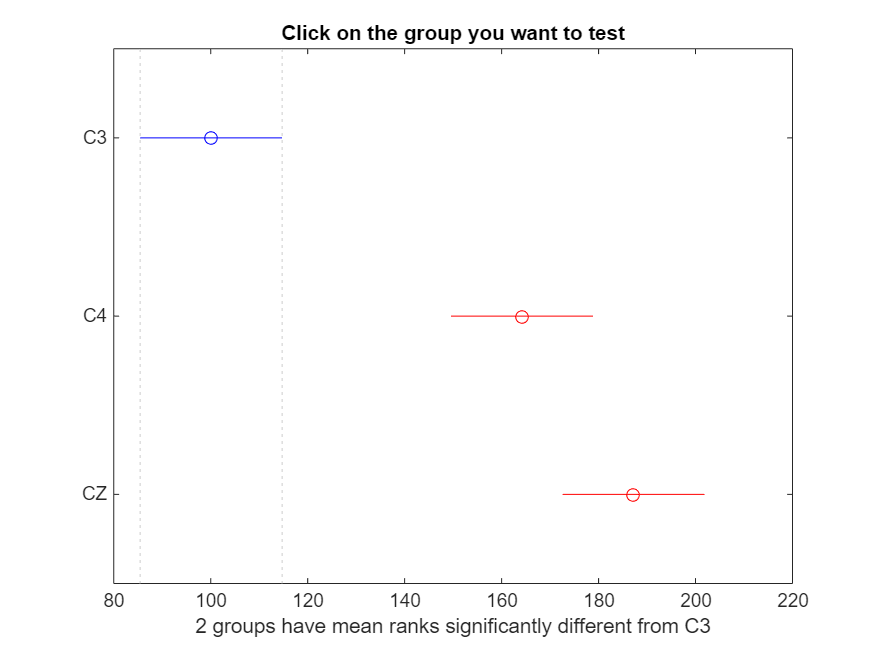

% Post-hoc after Kruskal-Wallis:
c_kw = multcompare(stats_kw, 'CType', 'dunn-sidak');

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


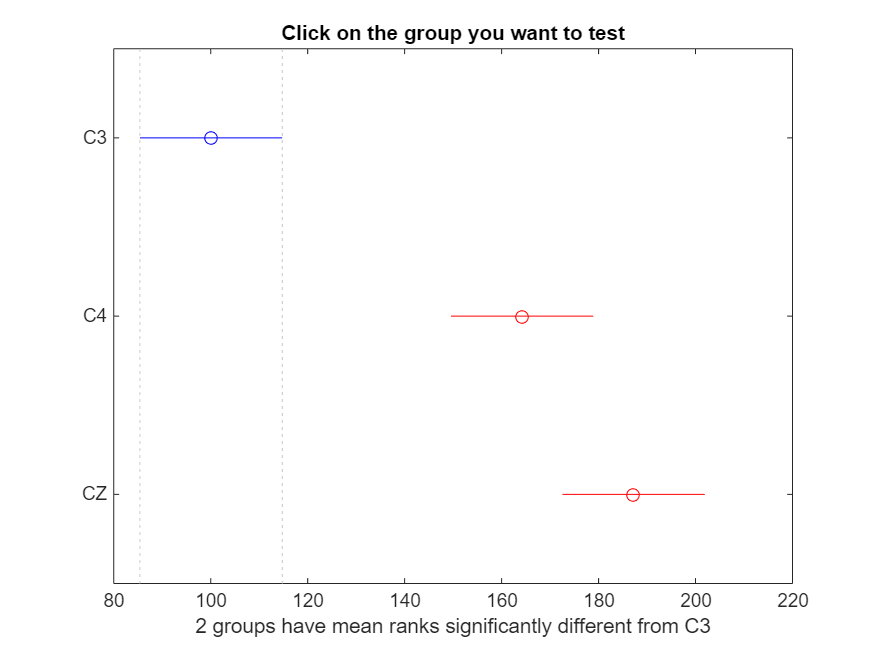

% Bonferroni post-hoc
c_kw = multcompare(stats_kw, 'CType', 'bonferroni');